**Romberg function is used here, Romberg.m file is also included.**

a=3 ;%amplitude 
fprintf('amplitude = %f',a)

amplitude = 3.000000

x=linspace(0,a .*(1-1 ./100),99);
f= @(x) (4 ./sqrt(2)) ./sqrt(a .^4 - x .^4);
n=length(x);
y=f(x);
T1=trapz(x,y);
T2=integral(f,x(1),x(n));
fprintf('Trapezoid method : T=%f \nAdaptive Integration Techiniques : T=%f',T1,T2)

Trapezoid method : T=1.143423 
Adaptive Integration Techiniques : T=1.141533



f2=@(x,y) (4 ./sqrt(2)) ./sqrt(y .^4 - x .^4);
amp=linspace(.1,5,100);
T=[];

for obj=amp(1:length(amp))
    T=[T,trapz(x,f2(x,obj))];

end 
   
plot(amp,T)

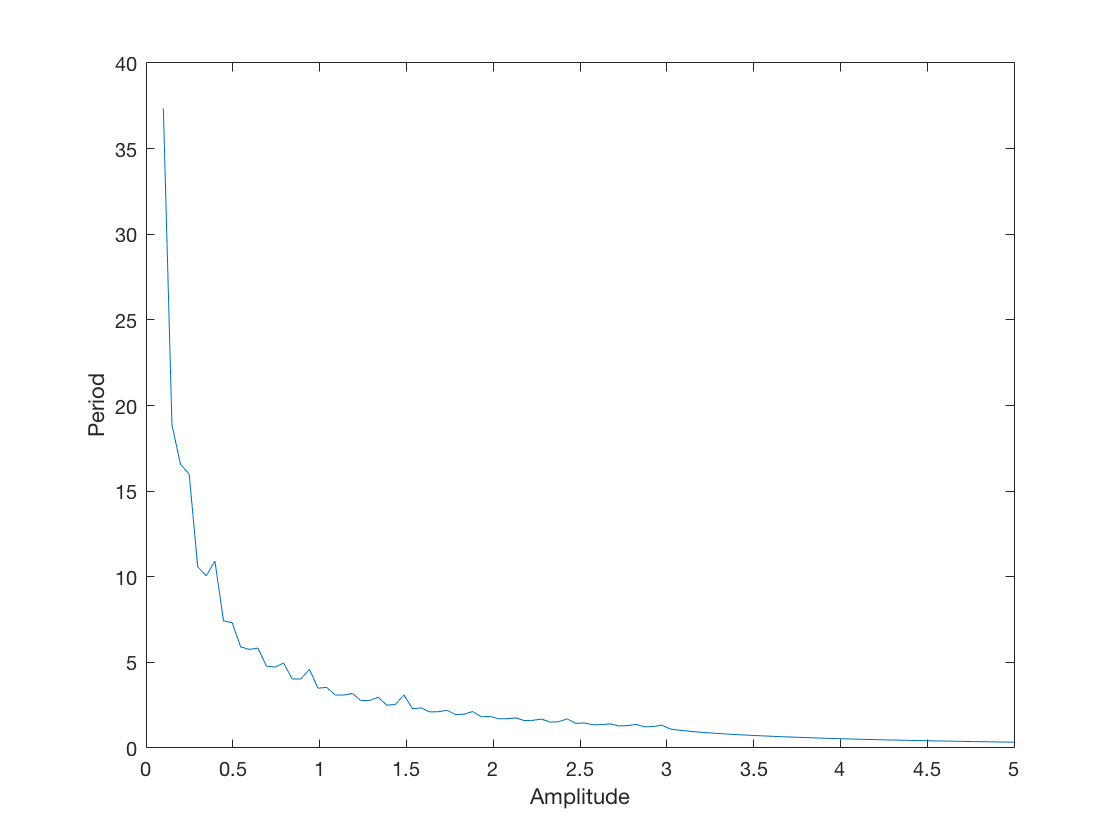

ans =      2


xlabel('Amplitude')
ylabel('Period')